# Week3 - Communications Channel with BPSK

The code below implements the BPSK modulation scheme and models a general communications channel in the electrical domain. 

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK

- A pulse shaper which creates an electrical signal using the generated symbols

### Modulation

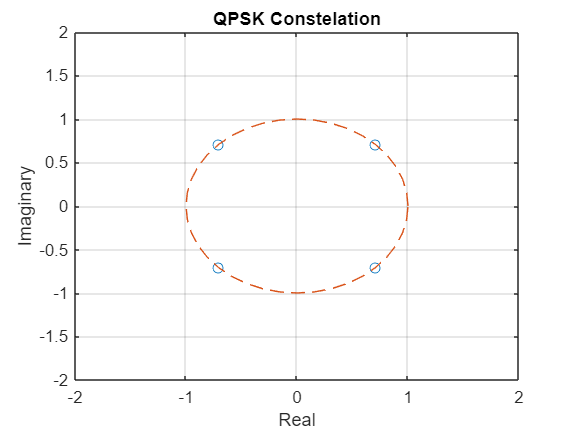

clear all; clearvars;

% Modulation parameters
M = 4; % Modulation order
k = log2(M); % Bits per symbol

% Visualising constellation
alphabet = 0:M-1;
symbols = pskmod(alphabet, M, pi/4);
plot(real(symbols), imag(symbols), "o");
title("QPSK Constelation");
xlabel("Real");
ylabel("Imaginary");
grid on;
hold on;
phase = [0:pi/20:2*pi];
circleX = cos(phase); circleY = sin(phase);
plot(circleX, circleY, "--");
xlim([-2,2]); ylim([-2,2])
hold off

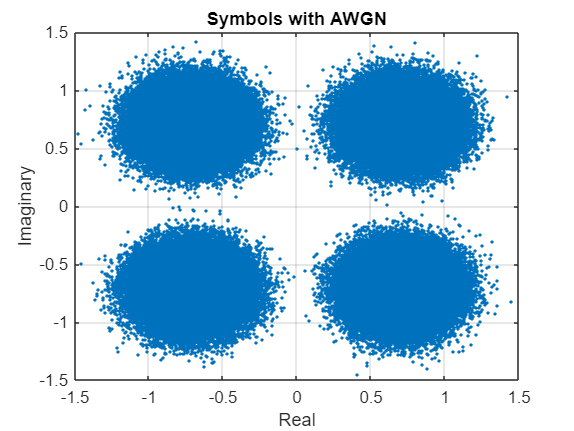


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
NSequences = 20; % No. of bit sequences

sourceBits = randi([0 1], NSymb*k, NSequences); % Matrix of source bits
sourceInts = bit2int(sourceBits, k);
sourceSymbols = pskmod(sourceInts, M, pi/4); % Maps source bit vector to symbol vector

% qpskmod mapping: 0-> 0.7071+0.7071i;  1-> -0.7071+0.7071i; 2-> 0.7071-0.7071i; 3-> -0.7071- 0.7071i

% Adding AWGN to the symbols
SNRb_dB = [0:NSequences-1]'; % SNR per bit in dB
powerPerSymb = mean(abs(symbols).^2,"all");
powerPerBit = powerPerSymb/k;

for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerBit/SNRb_Lin(i,1)); % AWGN Standard deviation
    sourceSymbols_AWGN(:,i) = sourceSymbols(:,i) + (1/sqrt(2))*AWGN_StdDev(i,1)*randn(size(sourceSymbols, 1),1) + (1i/sqrt(2))*AWGN_StdDev(i,1)*randn(size(sourceSymbols, 1),1); % Noisy symbols
end

% Visualising noisy symbols at SNR = 10 dB
plot(real(sourceSymbols_AWGN(:,11)), imag(sourceSymbols_AWGN(:,11)), ".");
title("Symbols with AWGN")
xlabel("Real")
ylabel("Imaginary")
grid on

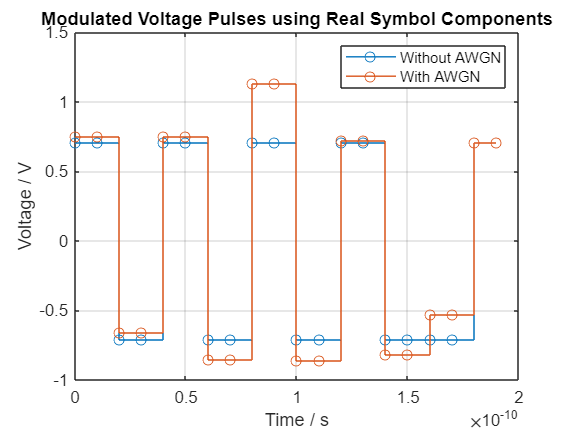


voltageWaveR = repelem(real(sourceSymbols), SpS, 1); % Matrix of real component of source symbols with oversampling based on SpS
voltageWaveR_AWGN = repelem(real(sourceSymbols_AWGN), SpS, 1); % Matrix of real componenent of source symbols with oversampling according to SpS

voltageWaveI = repelem(imag(sourceSymbols), SpS, 1); % Matrix of imag component of source symbols with oversampling based on SpS
voltageWaveI_AWGN = repelem(imag(sourceSymbols_AWGN), SpS, 1); % Matrix of imag componenent of source symbols with oversampling according to SpS

T = 1/(SpS*Rs); % Sampling period in sec
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Visualising voltage waveform
stairs(t(1:20), voltageWaveR(1:20,11), "o-");
title("Modulated Voltage Pulses using Real Symbol Components")
xlabel("Time / s")
ylabel("Voltage / V")
grid on
hold on
stairs(t(1:20), voltageWaveR_AWGN(1:20,11), "o-");
hold off
legend("Without AWGN", "With AWGN")

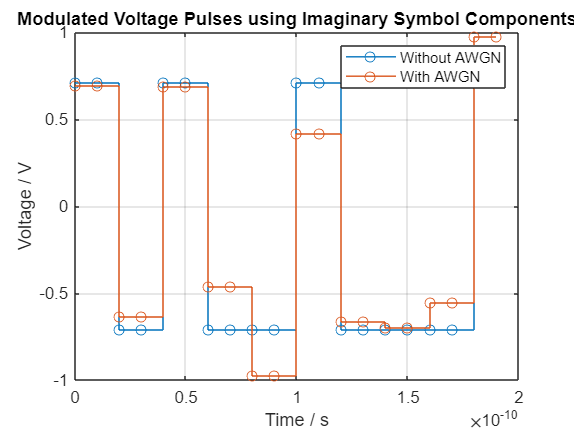


stairs(t(1:20), voltageWaveI(1:20,11), "o-");
title("Modulated Voltage Pulses using Imaginary Symbol Components")
xlabel("Time / s")
ylabel("Voltage / V")
grid on
hold on
stairs(t(1:20), voltageWaveI_AWGN(1:20,11), "o-");
hold off
legend("Without AWGN", "With AWGN")

### Pulse Shaping

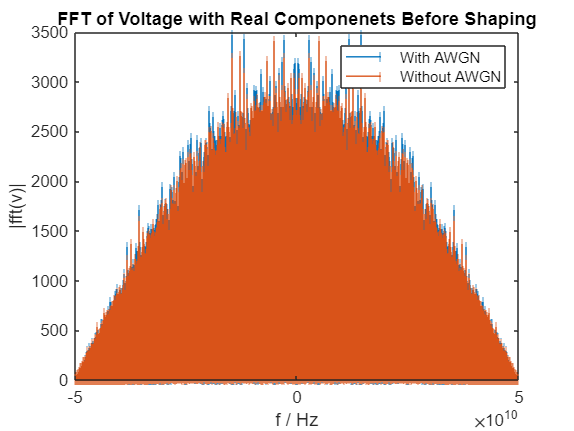

% Frequency spectrum of voltage waveform before filtering
fft_v_AWGN = fftshift(fft(voltageWaveR_AWGN(:,11)));
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
stem(freqArr, abs(fft_v_AWGN), "|");
title("FFT of Voltage with Real Componenets Before Shaping");
xlabel("f / Hz");
ylabel("|fft(v)|");
hold on
fft_v = fftshift(fft(voltageWaveR(:,11)));
stem(freqArr, abs(fft_v), "|");
legend("With AWGN", "Without AWGN")
hold off

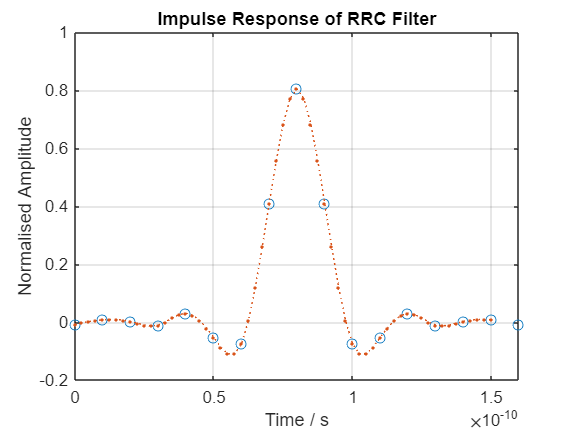


% Visualisation of RRC filter
filterSpan = 8; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
filterResponse_t_interp = [0:0.25:filterSpan*SpS - 1]*T;
filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

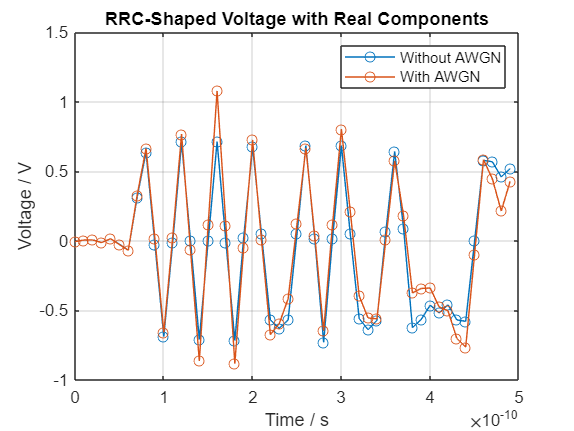


% The generated rectangular voltage pulses are shaped using the RRC filter
shapedVR= upfirdn(real(sourceSymbols), filterResponse, SpS, 1);
shapedVR_AWGN = upfirdn(real(sourceSymbols_AWGN), filterResponse, SpS, 1);

shapedVI = upfirdn(imag(sourceSymbols), filterResponse, SpS, 1);
shapedVI_AWGN = upfirdn(imag(sourceSymbols_AWGN), filterResponse, SpS, 1);

% Visualising pulse-shaped voltages
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
shapedV_t = [0:1:samples-1]*T; 

plot(shapedV_t(1:50), shapedVR(1:50,11), "-o");
hold on
plot(shapedV_t(1:50), shapedVR_AWGN(1:50,11), "-o");
title("RRC-Shaped Voltage with Real Components")
ylabel("Voltage / V")
xlabel('Time / s');
legend("Without AWGN", "With AWGN")
grid on
hold off

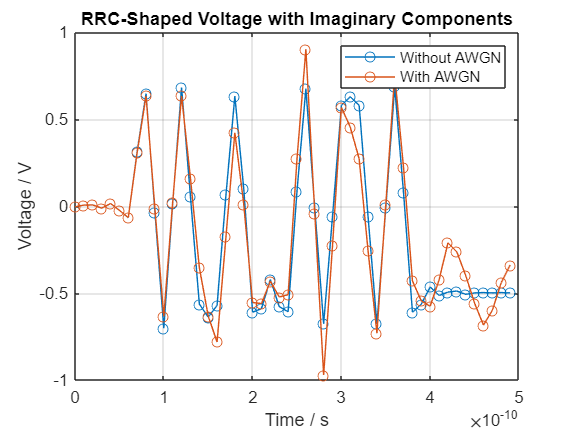


plot(shapedV_t(1:50), shapedVI(1:50,11), "-o");
hold on
plot(shapedV_t(1:50), shapedVI_AWGN(1:50,11), "-o");
title("RRC-Shaped Voltage with Imaginary Components")
ylabel("Voltage / V")
xlabel('Time / s');
legend("Without AWGN", "With AWGN")
grid on
hold off

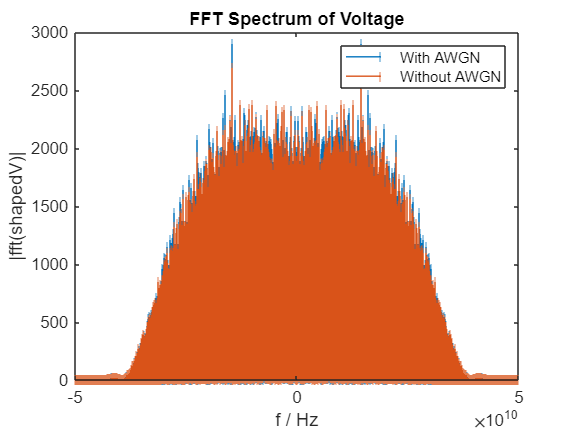


% Frequency spectrum of voltage waveform after filtering
fft_shapedV_AWGN = fftshift(fft(shapedVR_AWGN(:,11)));
freqArr = [-samples/2:samples/2 - 1]/(T*samples);
stem(freqArr, abs(fft_shapedV_AWGN), "|");
hold on
fft_shapedV = fftshift(fft(shapedVR(:,11)));
stem(freqArr, abs(fft_shapedV), "|");
title("FFT Spectrum of Voltage");
xlabel("f / Hz");
ylabel("|fft(shapedV)|");
legend("With AWGN", "Without AWGN")
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10

### Up-Conversion

% % Upconverted BPSK signal suitable for transmission
% 
% % Carrier wave
% c = 299792458; % Speed of light in air in m/s
% lambda = 1300e-9; % Wavelength of light in m
% fc = c/lambda % carrier frequency in Hz
% carrier = cos(2*pi*fc*shapedV_t)';
% 
% % Visualising carrier wave
% carrier_t = [0:0.25:4]/fc; carrier_t_interp = [0:0.125:4]/fc;
% plot(carrier_t, cos(2*pi*fc*carrier_t), "bo-", shapedV_t, carrier, "ro");
% title("Carrier")
% ylabel("Voltage / V")
% xlabel('Time / s');
% grid on
% 
% txOut = carrier.*shapedV;
% 
% % Frequency spectrum of voltage waveform after upconversion
% fft_txOut = fftshift(fft(txOut(:,1)));
% freqArr = [-samples/2:samples/2 - 1]*(fc+1/T)/samples;
% stem(freqArr, abs(fft_txOut), "|");
% title("FFT Spectrum of Voltage");
% xlabel("f / Hz");
% ylabel("|fft(shapedV)|");

## Channel

### Adding AWGN Noise

channelOutR = shapedVR;
channelOutR_AWGN = shapedVR_AWGN;

channelOutI = shapedVI;
channelOutI_AWGN = shapedVI_AWGN;

## Receiver

### Matched Filtering

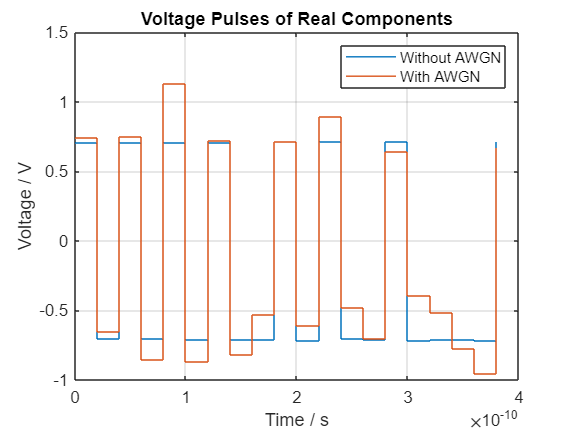

% Apply a matched filter to the recieved signal

% Without AWGN
% Extracting real components
filteredVoltageR = upfirdn(channelOutR, filterResponse, 1, SpS); % Filtering -> Downsampling
filteredVoltageR = filteredVoltageR(filterSpan + 1:end - filterSpan,:); % Removing additional samples from the tails
% Extracting Imaginary components
filteredVoltageI = upfirdn(channelOutI, filterResponse, 1, SpS); % Filtering -> Downsampling
filteredVoltageI = filteredVoltageI(filterSpan + 1:end - filterSpan,:); % Removing additional samples from the tails

% With AWGN
% Extracting real components
filteredVoltageR_AWGN = upfirdn(channelOutR_AWGN, filterResponse, 1, SpS); % Filtering -> Downsampling
filteredVoltageR_AWGN = filteredVoltageR_AWGN(filterSpan + 1:end - filterSpan,:); % Removing additional samples from the tails
% Extracting Imaginary components
filteredVoltageI_AWGN = upfirdn(channelOutI_AWGN, filterResponse, 1, SpS); % Filtering -> Downsampling
filteredVoltageI_AWGN = filteredVoltageI_AWGN(filterSpan + 1:end - filterSpan,:); % Removing additional samples from the tails


% Visualising recieved symbols
stairs([0:19]/Rs, filteredVoltageR(1:20,11));
hold on
stairs([0:19]/Rs, filteredVoltageR_AWGN(1:20,11));
title("Voltage Pulses of Real Components")
xlabel("Time / s")
ylabel("Voltage / V")
legend("Without AWGN", "With AWGN")
grid on
hold off

### Decision

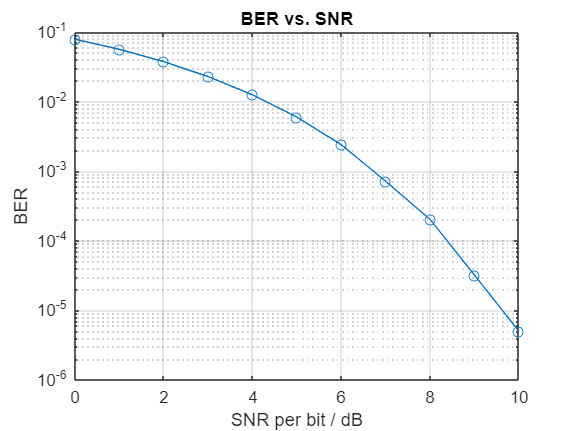

% Decoding the received symbols using ML detection

% The received symbols (with and without AWGN) is evaluated
receivedSymbols = filteredVoltageR + 1i*filteredVoltageI;
receivedSymbols_AWGN = filteredVoltageR_AWGN + 1i*filteredVoltageI_AWGN;

% The received symbols (with and without AWGN) are converted to bits
decodedInts = pskdemod(receivedSymbols, M, pi/4); decodedBits = int2bit(decodedInts, k);
decodedInts_AWGN = pskdemod(receivedSymbols_AWGN, M, pi/4); decodedBits_AWGN = int2bit(decodedInts_AWGN, k);

for i=1:NSequences
    [numErrors(i), BER(i)] = biterr(sourceBits(:,i), decodedBits_AWGN(:,i));
end

semilogy(SNRb_dB, BER, 'o-')
title("BER vs. SNR")
ylabel("BER")
xlabel("SNR per bit / dB")
grid on